# Focusing Gaussian beam

% Jonghwan Lee, Mar 2021

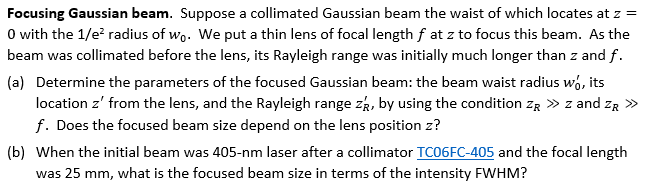

clear all
syms k w0 z positive
z_R = 1/2*k*w0^2;

## (a) After the lens

We can use the unapproximated formula, but here, since $z_R \gg z$ and $z_R \gg f$, $\frac{1}{\sqrt{1+ \left ( \frac{z_R}{z-f} \right ) ^2}} \simeq \frac{ \left | z-f \right | }{z_R}$ and thus $m \simeq \frac{f}{z_R}$.  Let us use this approximation for simplicity (the final graphs change negligibly).

syms f positive

r = z_R / (z-f);
m = f/abs(z-f) / sqrt(1+r^2)  % unapproximated

$$m = \frac{f}{\left|f-z\right|\,\sqrt{\frac{k^{2}\,{w_{0}}^{4}}{4\,{\left(f-z\right)}^{2}}+1}}$$


m = f/z_R  % approximated

$$m = \frac{2\,f}{k\,{w_{0}}^{2}}$$


w0p = m*w0

$$w0p = \frac{2\,f}{k\,w_{0}}$$

zp = f + m^2 * (z-f)

$$zp = f-\frac{4\,f^{2}\,\left(f-z\right)}{k^{2}\,{w_{0}}^{4}}$$

z_Rp = m^2*z_R

$$z\_Rp = \frac{2\,f^{2}}{k\,{w_{0}}^{2}}$$

- $w_0'$ does not depend on $z$.

## (b) Using the real-world collimator

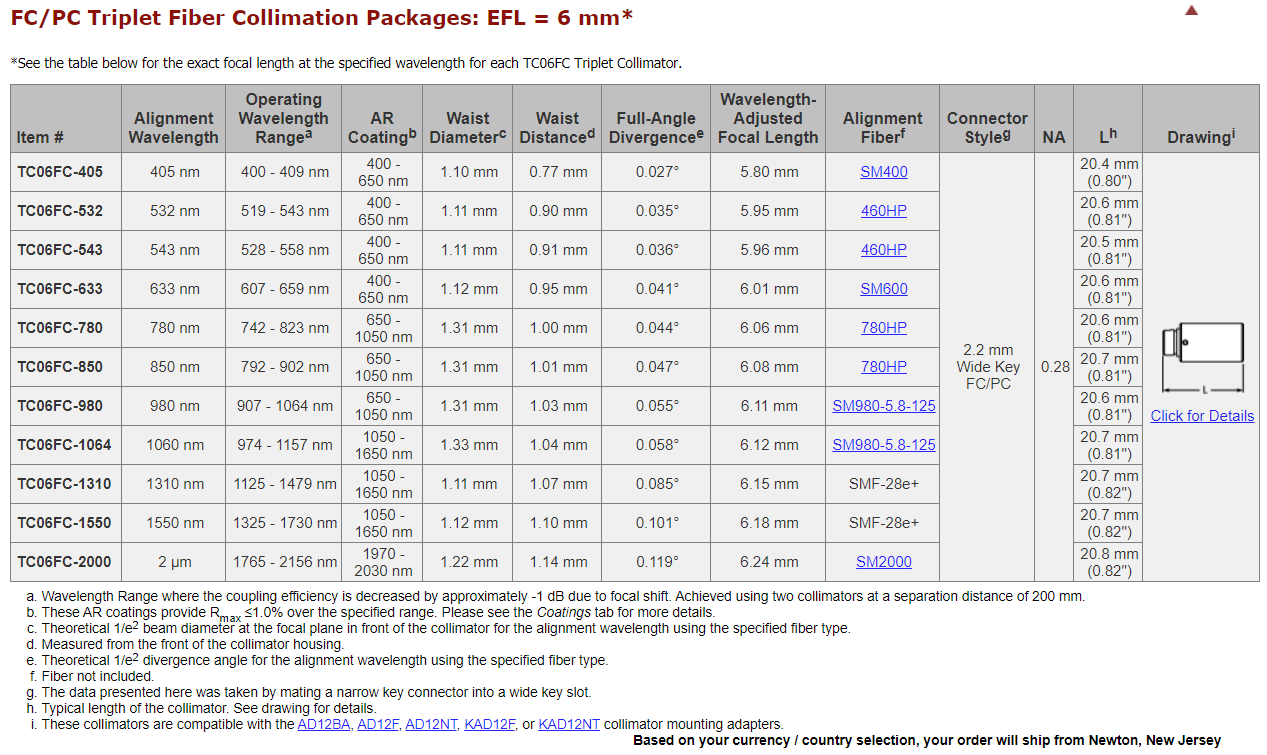

w0p(k,w0,f) = w0p

$$w0p(k, w0, f) = \frac{2\,f}{k\,w_{0}}$$


% all lengths are in [mm].
lam = 405e-6;  
w0Val = 1.10/2;

kVal = 2*pi/lam;
fVal = 25;

w0pVal = vpa(w0p(kVal,w0Val,fVal),2)

$$w0pVal = 5.9e-3$$


fwhm = vpa( 2*sqrt(2*log(2))* w0pVal/2 , 2)  % intensity RMS or STD = w0/2

$$fwhm = 6.9e-3$$